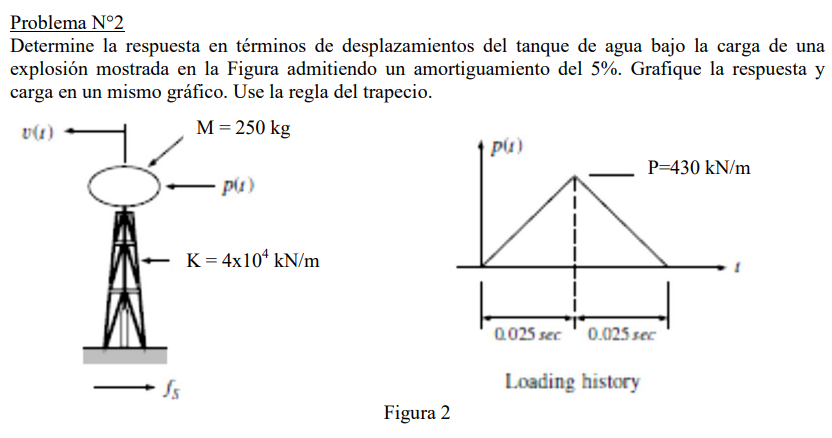

## Respuesta para comparar resultados

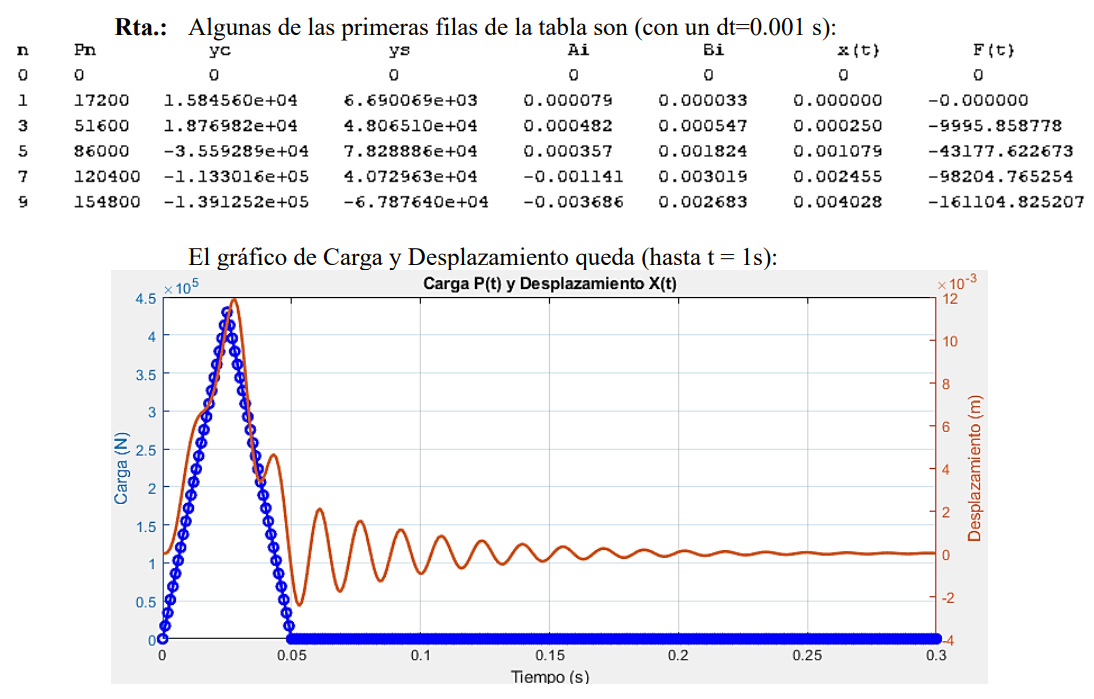

clc; clear;

dt=0.001;
tf=0.3;
t=0:dt:tf;

e=exp(1);

%% ---------------PARÁMETROS DEL SISTEMA-----------------------
m=250;
zeta=0.05;
k=4000*10^4;

w=sqrt(k/m);
c=zeta*2*m*w;
wd=w*sqrt(1-zeta^2);

%% ------------- DESCRIPCIÓN DE FUERZA EXTERNA ---------------

P=zeros(1,length(t));
Po = 430000; %valor máximo de la función
u = 0.025; %donde se logra el pico de la función

for i=1:length(t)
    ti = t(i);
    P(i) = (ti>0).* (ti<=u) .* (Po/u*ti) + (ti>u).* (ti<=2*u) .* (-Po/u*ti+2*Po);
end


%% ------------ CALCULO INTEGRAL DE DUHAMEL ------------------

yc = P.*cos(w*t); %Se usa en la integral duhamel
ys = P.*sin(w*t); %Se usa en la integral de duhamel

A = zeros(1,length(t)); %Se usa en la integral de duhamel
B = zeros(1,length(t)); %Se usa en la integral de duhamel

for i=2:length(t)
    A(i) = A(i-1)*e^(-zeta*w*dt) + dt/(2*w*m) * (yc(i-1)*e^(-zeta*w*dt) + yc(i));
    B(i) = B(i-1)*e^(-zeta*w*dt) + dt/(2*w*m) * (ys(i-1)*e^(-zeta*w*dt) + ys(i));
end

x = A.*sin(w*t) - B.*cos(w*t);

P

P = 1.0e+05 *

         0    0.1720    0.3440    0.5160    0.6880    0.8600    1.0320    1.2040    1.3760    1.5480    1.7200    1.8920    2.0640    2.2360    2.4080    2.5800    2.7520    2.9240    3.0960    3.2680    3.4400    3.6120    3.7840    3.9560    4.1280    4.3000    4.1280    3.9560    3.7840    3.6120    3.4400    3.2680    3.0960    2.9240    2.7520    2.5800    2.4080    2.2360    2.0640    1.8920    1.7200    1.5480    1.3760    1.2040    1.0320    0.8600    0.6880    0.5160    0.3440    0.1720


yc

yc = 1.0e+05 *

         0    0.1584    0.2397    0.1870   -0.0201   -0.3579   -0.7610   -1.1344   -1.3737   -1.3882   -1.1243   -0.5815    0.1806    1.0476    1.8676    2.4772    2.7332    2.5421    1.8835    0.8211   -0.5005   -1.8757   -3.0692   -3.8565   -4.0648   -3.6080   -2.3157   -0.7688    0.7682    2.0527    2.9029    3.2229    3.0119    2.3564    1.4082    0.3528   -0.6256   -1.3759   -1.8034   -1.8810   -1.6472   -1.1919   -0.6339   -0.0947    0.3258    0.5679    0.6196    0.5154    0.3231    0.1258


ys

ys = 1.0e+05 *

         0    0.0670    0.2468    0.4809    0.6877    0.7820    0.6971    0.4033   -0.0803   -0.6850   -1.3017   -1.8004   -2.0561   -1.9754   -1.5201   -0.7209    0.3207    1.4448    2.4572    3.1632    3.4034    3.0868    2.2133    0.8818   -0.7196   -2.3393   -3.4173   -3.8806   -3.7052   -2.9721   -1.8458   -0.5412    0.7168    1.7312    2.3644    2.5558    2.3253    1.7625    1.0039    0.2039   -0.4952   -0.9878   -1.2213   -1.2003   -0.9792   -0.6458   -0.2990   -0.0256    0.1181    0.1173


A

A =          0    0.0001    0.0003    0.0005    0.0006    0.0004   -0.0002   -0.0011   -0.0024   -0.0037   -0.0049   -0.0056   -0.0057   -0.0050   -0.0034   -0.0012    0.0014    0.0040    0.0061    0.0073    0.0073    0.0060    0.0034   -0.0001   -0.0040   -0.0077   -0.0105   -0.0118   -0.0116   -0.0099   -0.0073   -0.0041   -0.0009    0.0017    0.0036    0.0044    0.0041    0.0031    0.0014   -0.0004   -0.0022   -0.0035   -0.0044   -0.0046   -0.0044   -0.0039   -0.0032   -0.0026   -0.0021   -0.0019


B

B =          0    0.0000    0.0002    0.0005    0.0011    0.0018    0.0025    0.0030    0.0031    0.0027    0.0016    0.0001   -0.0019   -0.0038   -0.0055   -0.0065   -0.0065   -0.0055   -0.0035   -0.0006    0.0026    0.0058    0.0083    0.0097    0.0095    0.0078    0.0048    0.0011   -0.0027   -0.0059   -0.0082   -0.0092   -0.0089   -0.0075   -0.0053   -0.0028   -0.0003    0.0017    0.0030    0.0036    0.0034    0.0025    0.0014    0.0002   -0.0009   -0.0017   -0.0021   -0.0022   -0.0021   -0.0020


x

x =          0         0    0.0001    0.0002    0.0006    0.0011    0.0017    0.0025    0.0032    0.0040    0.0047    0.0053    0.0058    0.0062    0.0064    0.0065    0.0066    0.0068    0.0070    0.0072    0.0076    0.0081    0.0087    0.0094    0.0101    0.0108    0.0114    0.0118    0.0119    0.0115    0.0108    0.0097    0.0085    0.0071    0.0058    0.0047    0.0039    0.0035    0.0033    0.0035    0.0038    0.0042    0.0045    0.0046    0.0045    0.0040    0.0033    0.0024    0.0013    0.0002


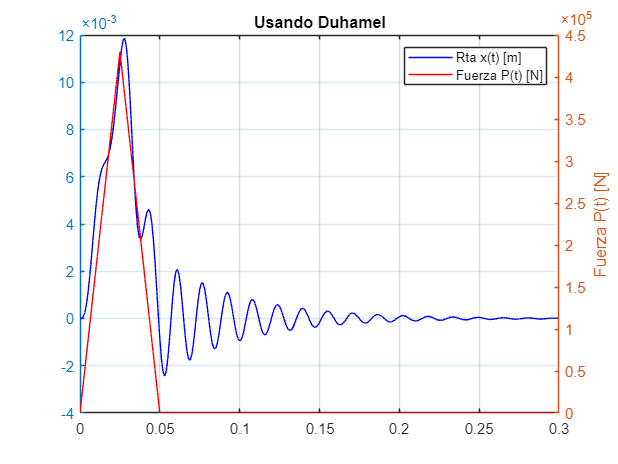


figure(1)
title('Usando Duhamel')
yyaxis left
plot(t,x,'b')

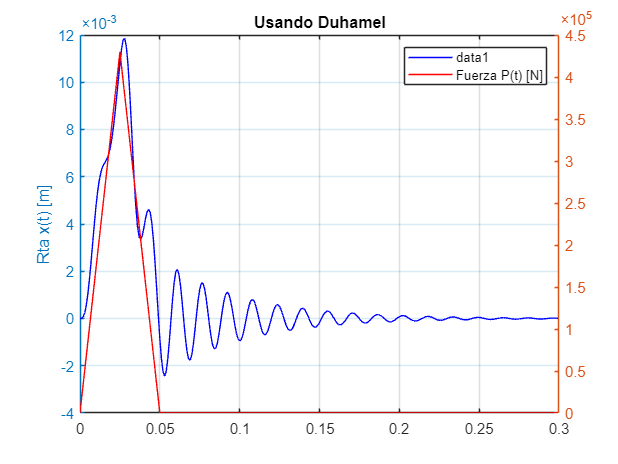

ylabel('Rta x(t) [m]')

yyaxis right
plot(t,P,'r');

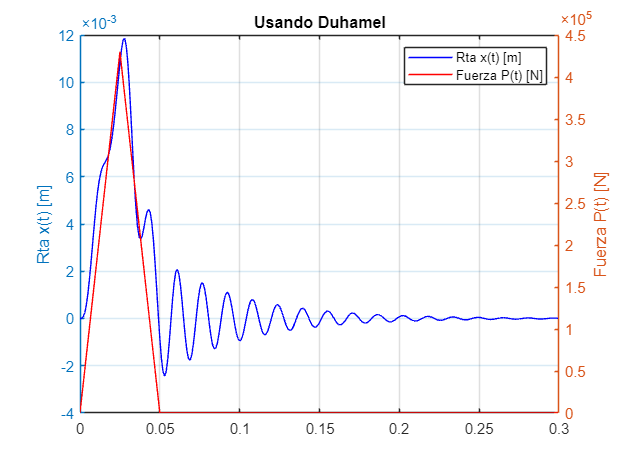

ylabel('Fuerza P(t) [N]')
legend('Rta x(t) [m]', 'Fuerza P(t) [N]');

grid on


%% ------------ APROXIMACIÓN POR IMPULSO ------------------

%Se da cuando el tiempo de aplicación de la carga es menor a al 25% del
%periodo del sistema.
%Cuando esto ocurre, el impulso es el área bajo la curva de la carga y
%dividiendola por (wd*m) podemos calcular una velocidad inicial y tratar al
%sistema como si fuera un caso de vibraciones libres.

T = 2*pi/w;     %Periodo del sistema
t_P = 0.005;     %Tiempo de aplicacion de la carga. Se ve en el gráfico

if t_P<0.25*T
    disp("t_p es menor al 0.25*T. Puedo aproximar por impulso unitario.")
    
    impulso = trapz(t,P); %El impulso es el área bajo la curva P
    e=exp(1);
    
    xaprox = impulso/(wd*m) .* sin(wd*t) .* e.^(-zeta*w*t);
    
    figure(2)
    title('Aproximación por impulso unitario')
    yyaxis left
    plot(t,x,'b', t,xaprox,'g')
    ylabel('Rta x(t) [m]')
    
    yyaxis right
    plot(t,P,'r');
    ylabel('Fuerza P(t) [N]')
    legend('x(t) Duhamel', 'x(t) impulso unitario', 'Fuerza P(t) [N]');
    
end



